# **Computer tomography Implement **

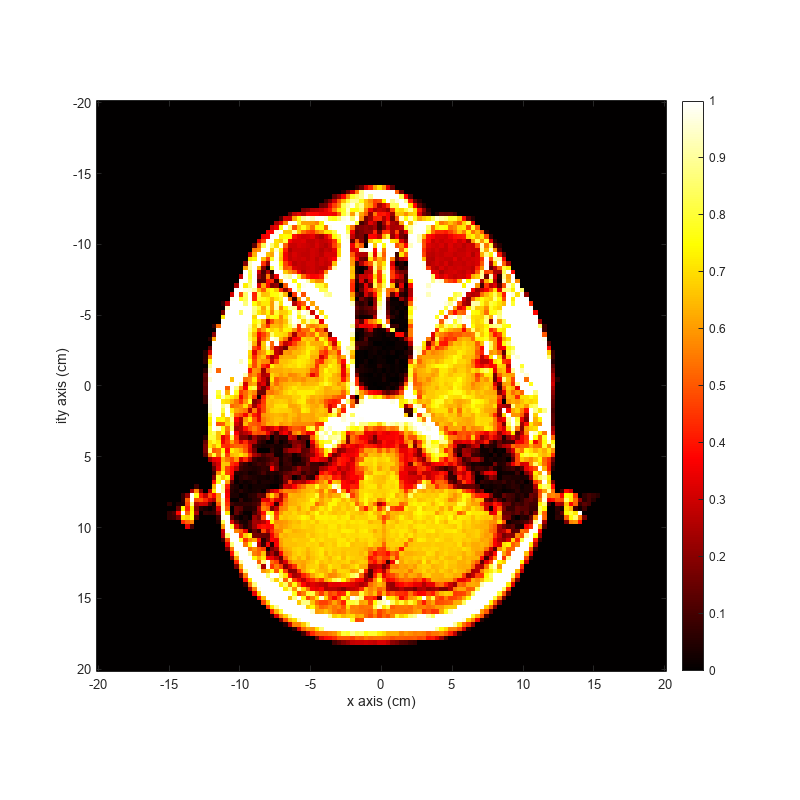

% 清除工作空間,清除命令視窗,關閉所有視窗
clear;clc;close all;
%載入名為"mri.mat"的MATLAB檔案,其中包含了3D MRI影像資料
load("mri.mat");
%將3D影像資料D擠壓成2D矩陣vol。
vol = squeeze(D);
%選取vol的第5個slice,並將其資料值重新縮放到0到1之間
sliceZ = rescale(double(vol(:,:,5)),0,1);
%取得slice的大小
[height,width] = size(sliceZ);
%建立一個長度為width的向量t,範圍從-20cm到20cm
t = linspace(-20,20,height)';
s = t;
%顯示選取的slice,並使用灰階色彩圖,並加上色彩條
fig = figure;
fig.Position(3) = 1000;
fig.Position(4) = 1000;
imagesc(t,s,sliceZ);colormap hot;colorbar;axis equal tight;
xlabel('\itx axis (cm)');ylabel('ity axis (cm)')

%建立一個3D矩陣,用於儲存每個角度下旋轉後的slice影像
slice_deg = zeros(height,width,360);
%建立一個2D矩陣,用於儲存每個角度下的投影數據
detect_array = zeros(height,360);

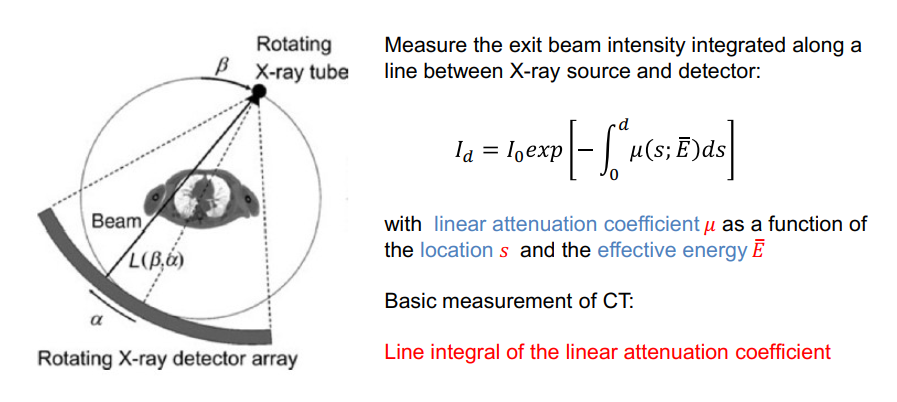

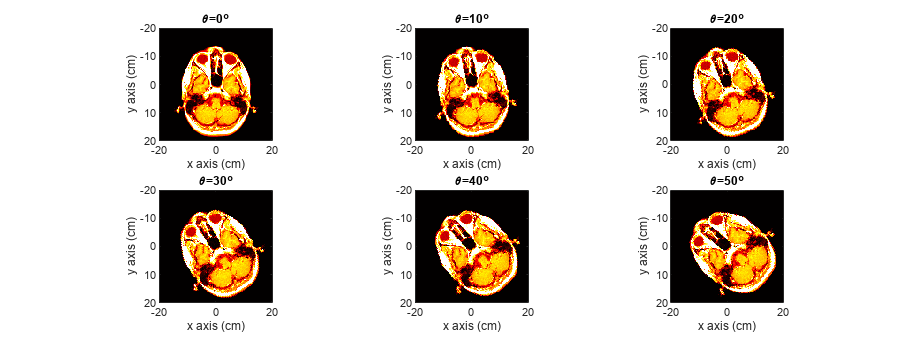

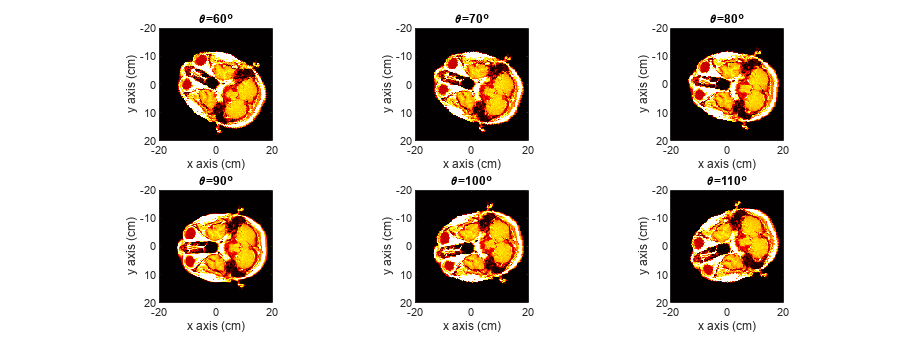

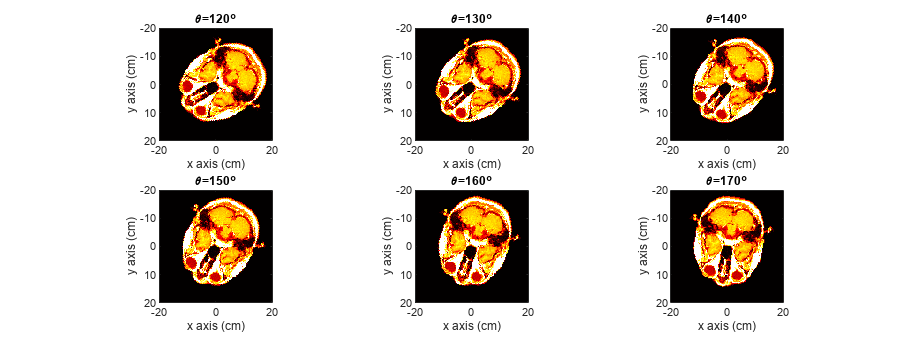

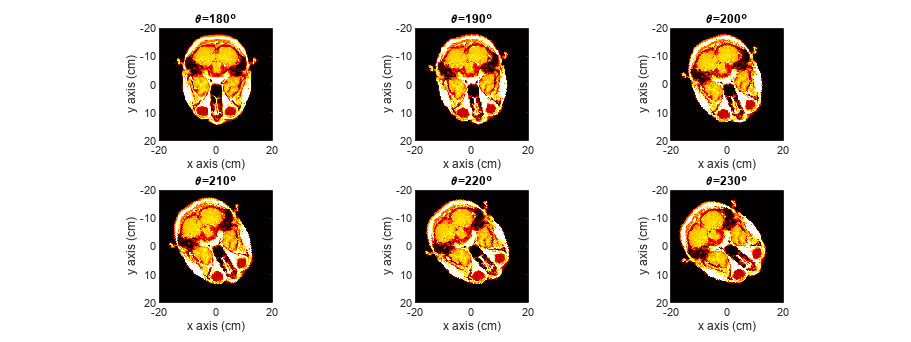

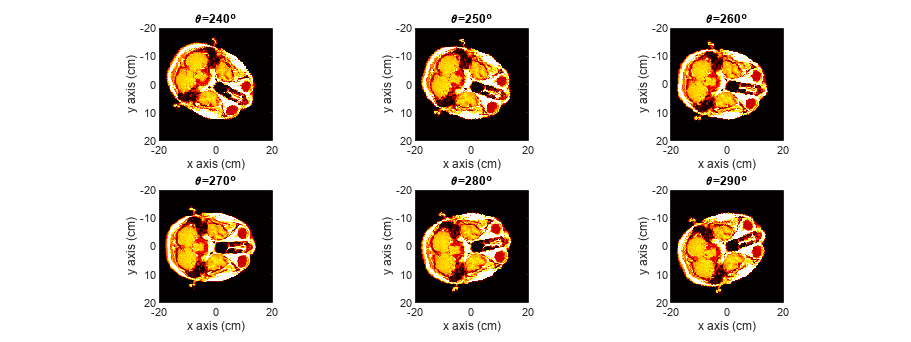

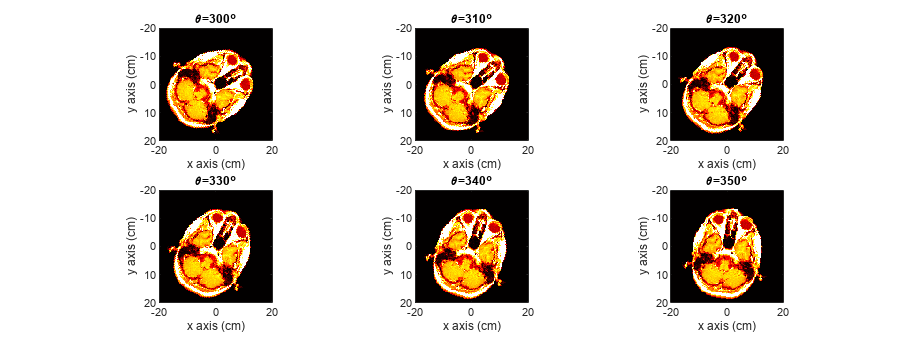

count = 6;
for deg = 0:359
    %對slice影像進行0到359度的旋轉,並將結果存入slice_deg矩陣
    rotate_image = circshift(imrotate(sliceZ,deg,'crop'),[ceil(rand(1)-0.5*0), ceil(rand(1)-0.5*0)]);
    slice_deg(:,:,deg+1) = rotate_image;

    %每隔20度,將當前角度下的旋轉slice顯示一個圖
    a = rem(deg,10);%余数
    if a == 0
        if count == 6
            count = count -5;
            fig = figure(); 
            fig.Position(3:4) = [8000, 3000];
        else
            count = count +1;
        end
        subplot(2,3,count)
        imagesc(t,s,rotate_image);colormap hot;axis equal tight;
        xlabel('\itx axis (cm)');ylabel('\ity axis (cm)')
        title(['\theta=',num2str(deg),'\circ'])
        drawnow
    end
end

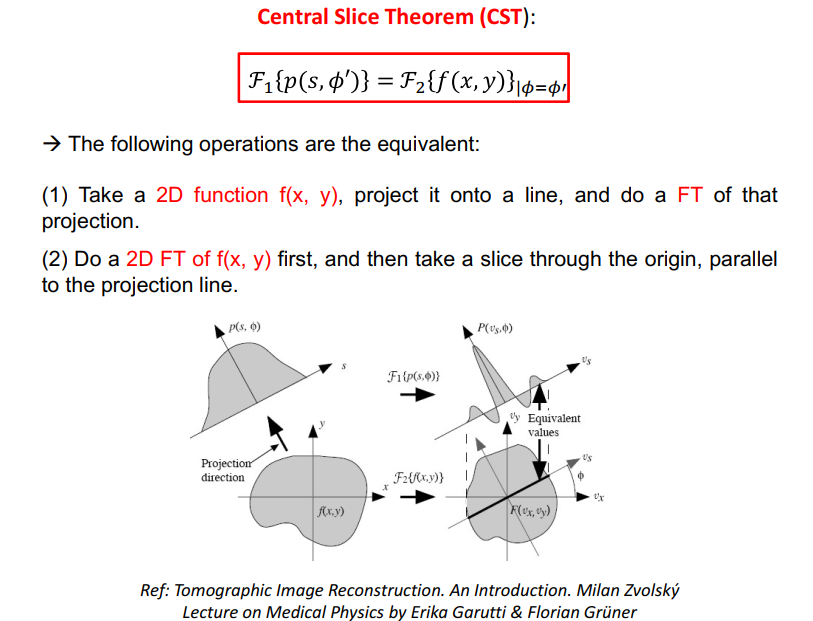

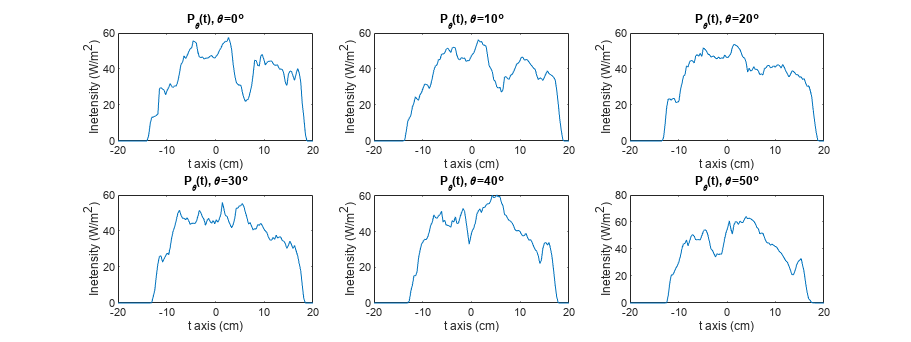

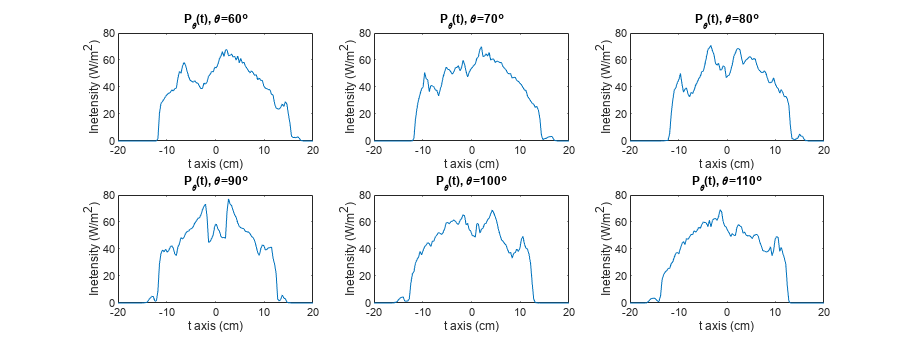

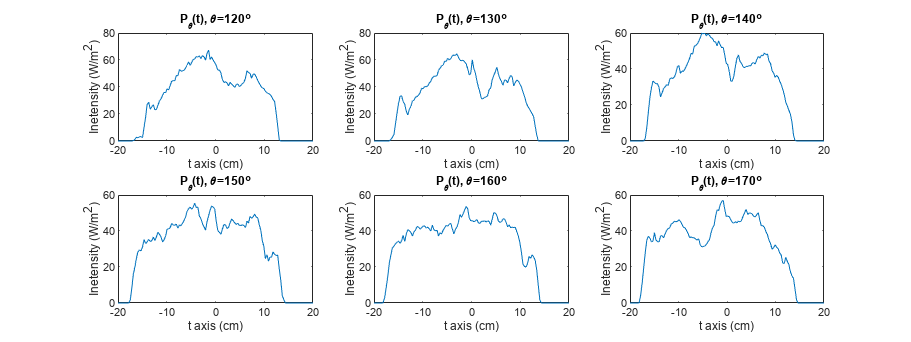

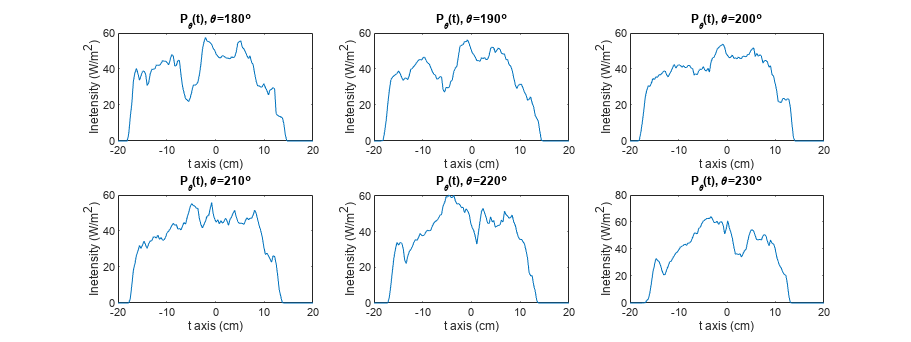

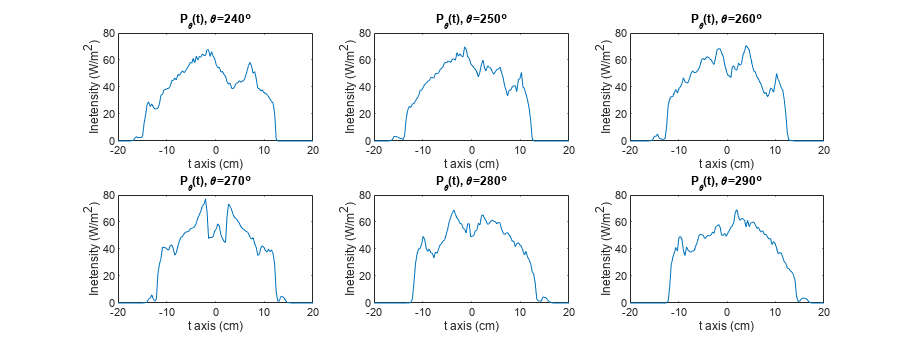

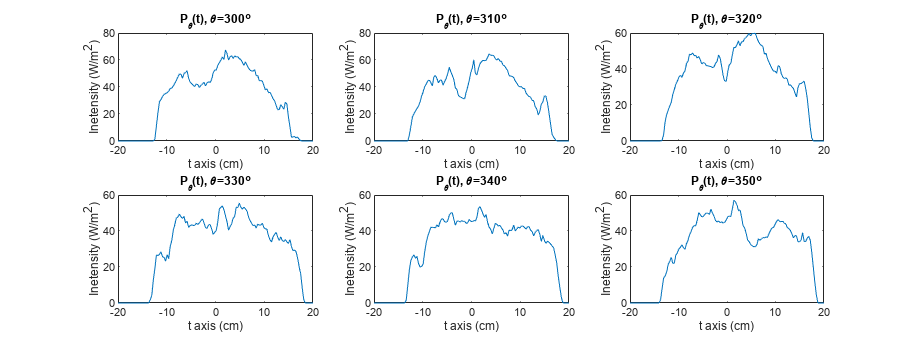

count = 6;
for deg = 0:359
    %對每個角度下的旋轉slice,計算其投影(投影振幅)並存入detect_array矩陣
    detect = squeeze(sum(slice_deg(:,:,deg+1),2));
    detect_array(:,deg+1) = detect;

    %每隔60度,將當前角度下的投影數據繪製在一個3x2的子圖中
    a = rem(deg,10);%余数
    if a == 0
        if count == 6
            count = count -5;
            fig = figure(); 
            fig.Position(3:4) = [8000, 3000];
        else
            count = count +1;
        end
        subplot(2,3,count)
        plot(t,detect);
        xlabel('\itt axis (cm)');ylabel('Inetensity (W/m^2)')
        title(['P_{\theta}(t), \theta=',num2str(deg),'\circ'])
        drawnow
    end
end

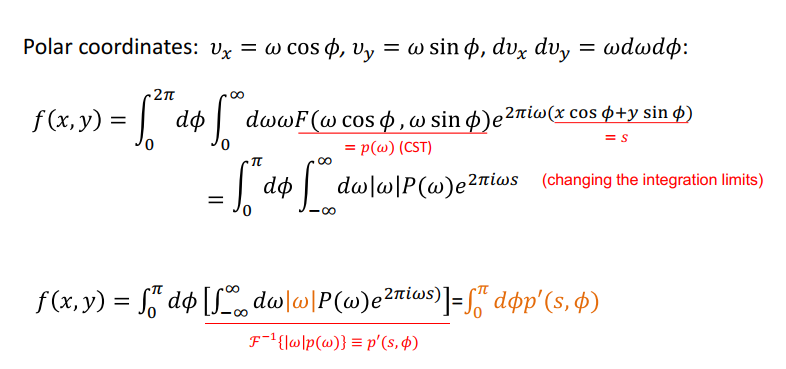

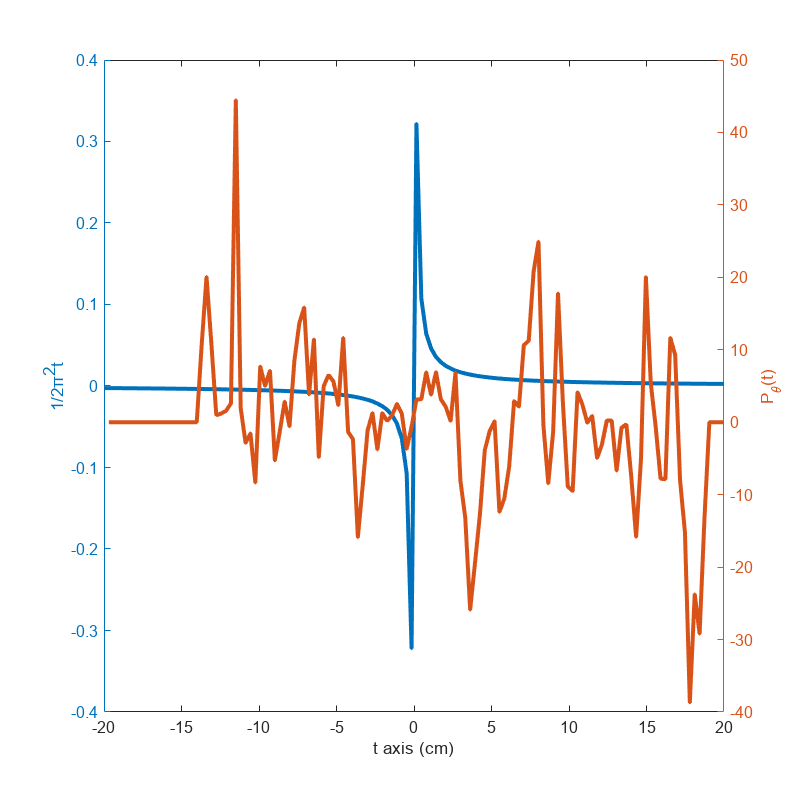

%計算detect_array的導數dPdt,並繪製dPdt和1/2πt的圖形
fig = figure(); 
fig.Position(3:4) = [1000, 1000];
dPdt = diff(detect_array)./repmat(diff(t),[1 360]);
sgn = 1./(2*pi^2*t);
deg = 1;
yyaxis right
plot(t(2:end),dPdt(:,1),'LineWidth',3);
xlabel('\itt axis (cm)');ylabel('P_{\theta}(t)')
yyaxis left
plot(t,sgn,'LineWidth',3);
xlabel('\itt axis (cm)');ylabel('1/2π^{2}t')
set(gca,'fontsize',12)

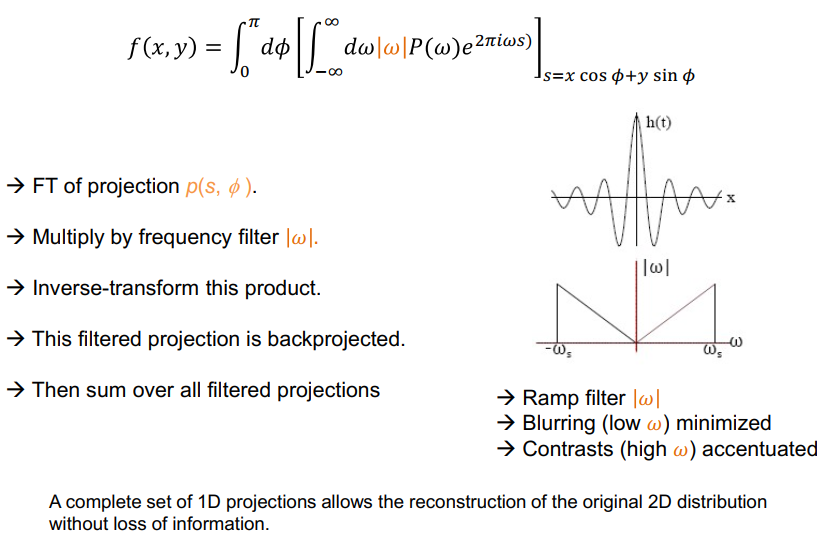

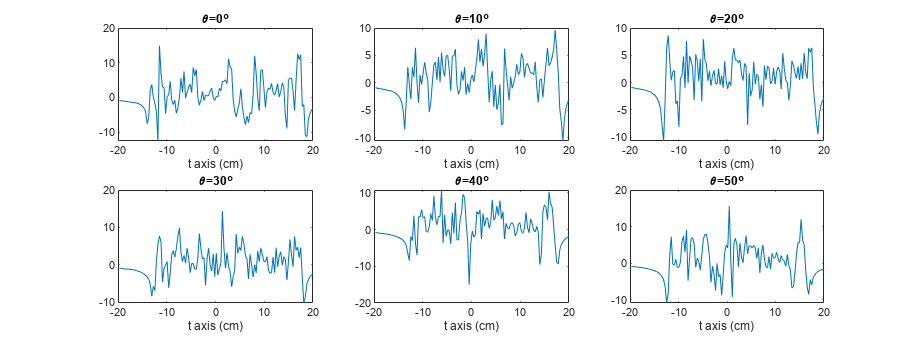

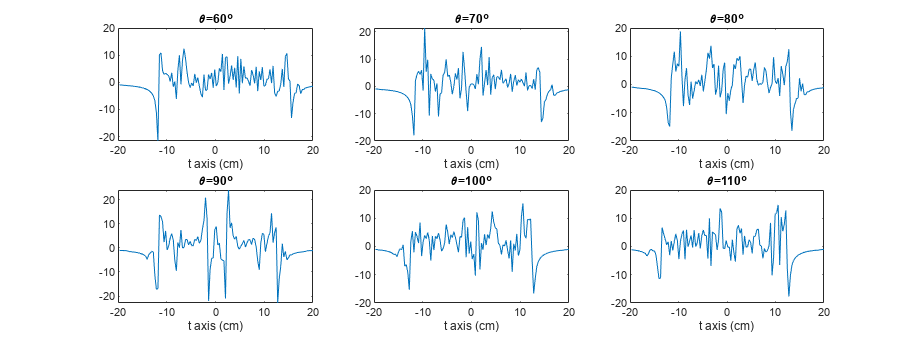

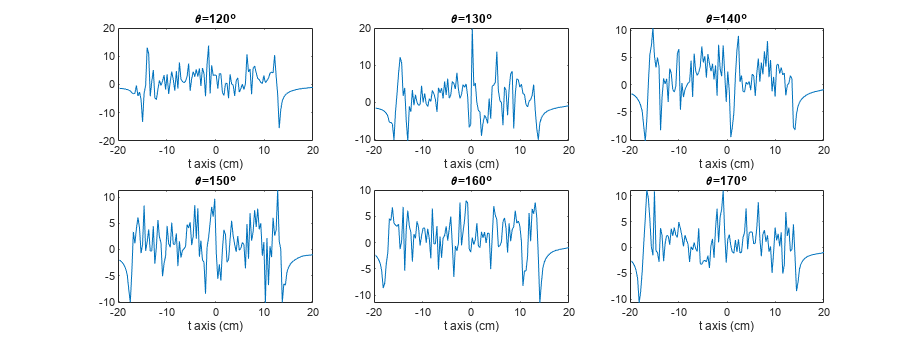

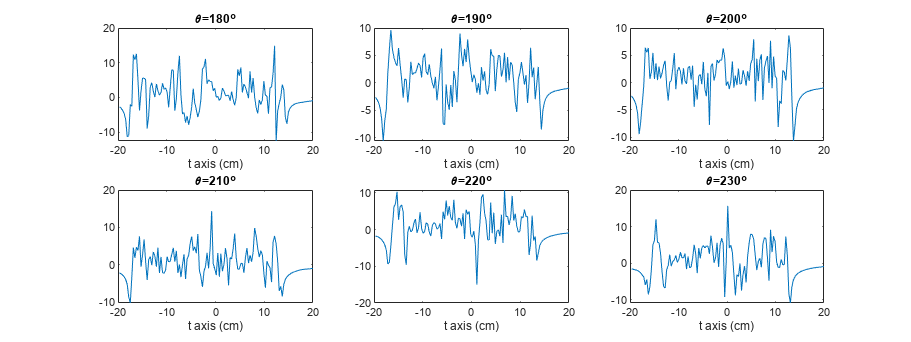

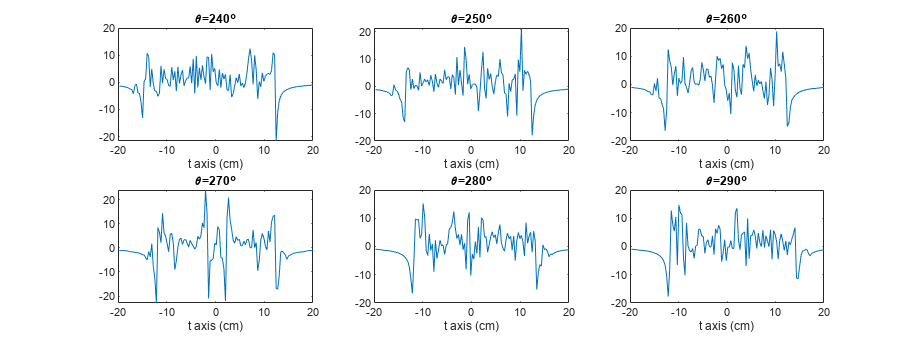

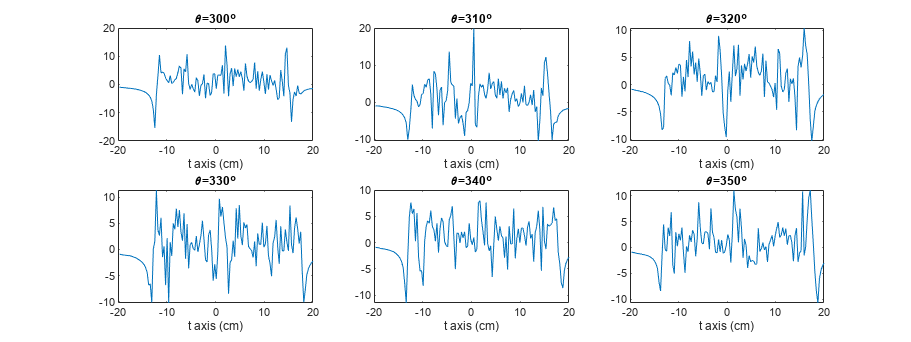

count = 6;
for deg = 0:359
    %對每個角度下的投影數據,與1/2πt進行卷積運算,得到ptheta值
    ptheta = conv(dPdt(:,deg+1),sgn,'same');
    Ptheta(:,:,deg+1) = ptheta;
    
    %每隔60度,將當前角度下的ptheta值繪製在一個3x2的子圖中
    a = rem(deg,10);%余数
    if a == 0
        if count == 6
            count = count -5;
            fig = figure(); 
            fig.Position(3:4) = [8000, 3000];
        else
            count = count +1;
        end
        subplot(2,3,count)
        plot(t(2:end),ptheta);
        title(['\theta=',num2str(deg),'\circ'])
        xlabel('\itt axis (cm)')
        drawnow
    end
end

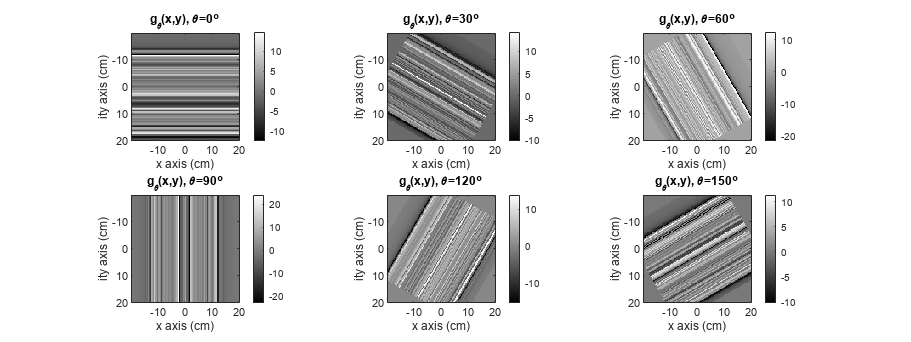

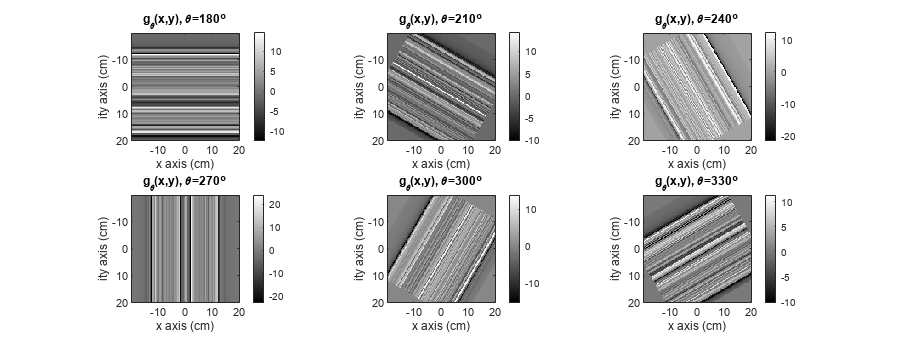

count = 6;
for deg = 0:359
    %對每個角度下,將ptheta數據轉換為2D影像gxy,並存入gxy3D矩陣
    I_item = Ptheta(:,1,deg+1);
    gts = repmat(I_item,[1 127]);
    gxy = imrotate(gts,-deg,'crop');
    gxy3D(:,:,deg+1) = gxy;

    %每隔60度,將當前角度下的gxy影像繪製在一個3x2的子圖中
    a = rem(deg,30);%余数
    if a == 0
        if count == 6
            count = count -5;
            fig = figure(); 
            fig.Position(3:4) = [8000, 3000];
        else
            count = count +1;
        end
        subplot(2,3,count)
        imagesc(t(2:end),t(2:end),gxy);colormap gray;colorbar;axis equal tight;
        xlabel('\itx axis (cm)');ylabel('ity axis (cm)')
        title(['g_{\theta}(x,y), \theta=',num2str(deg),'\circ'])
        drawnow
    end
end

gxy3D(:,:,361) = gxy;

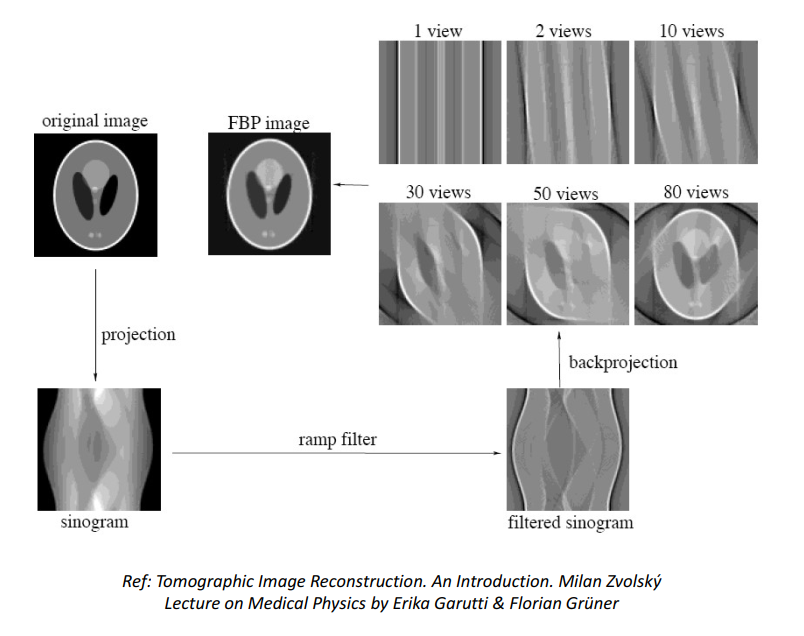

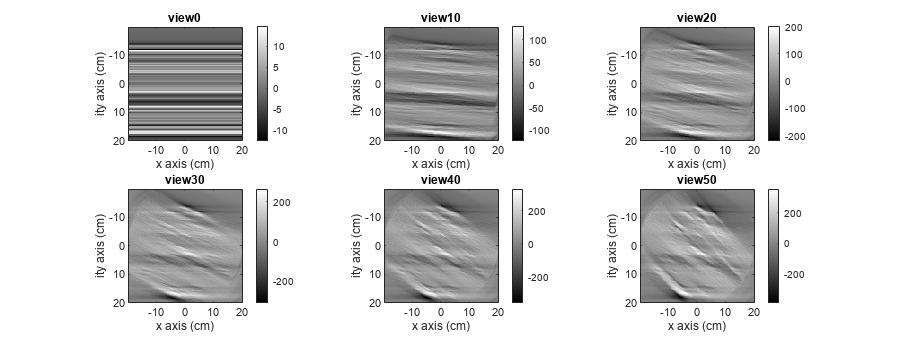

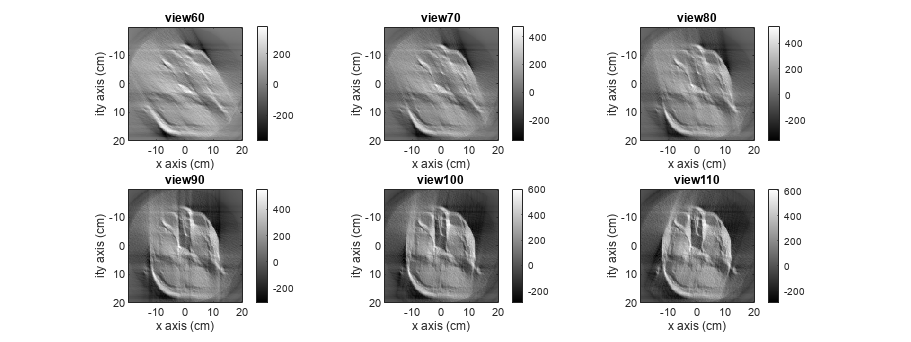

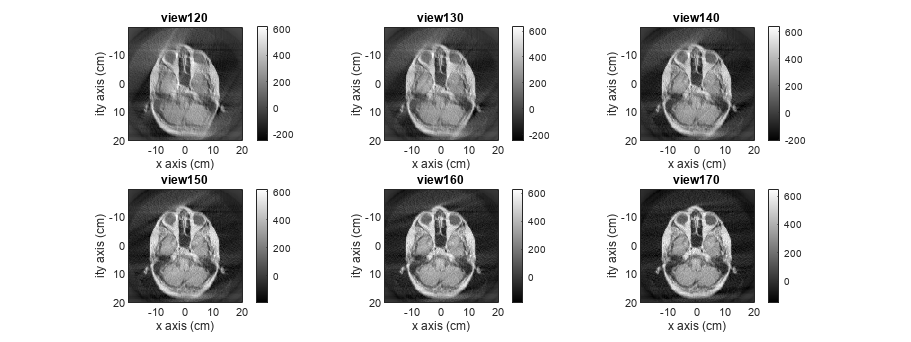

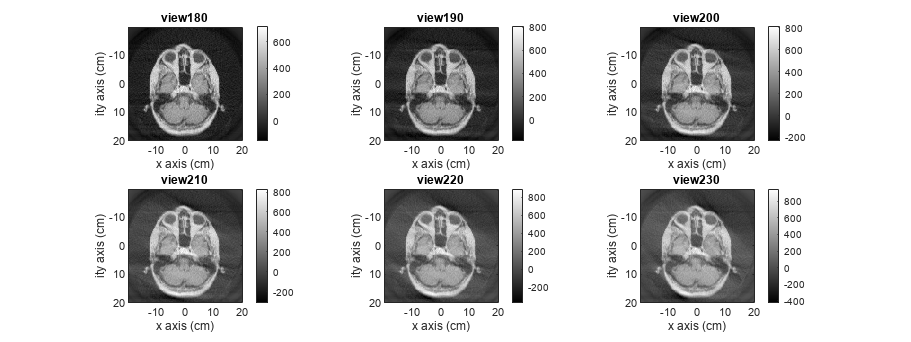

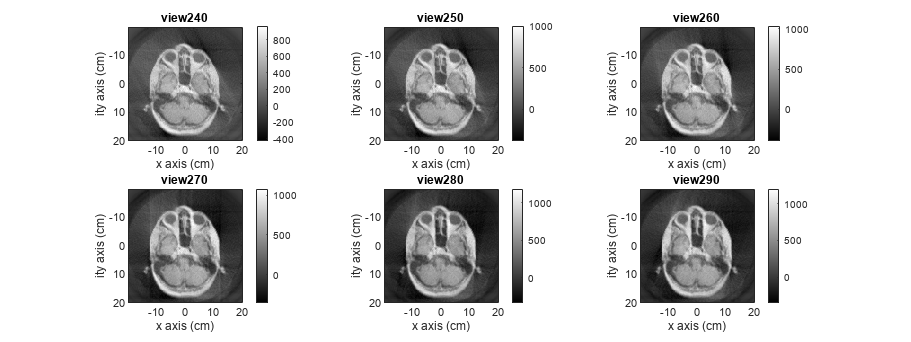

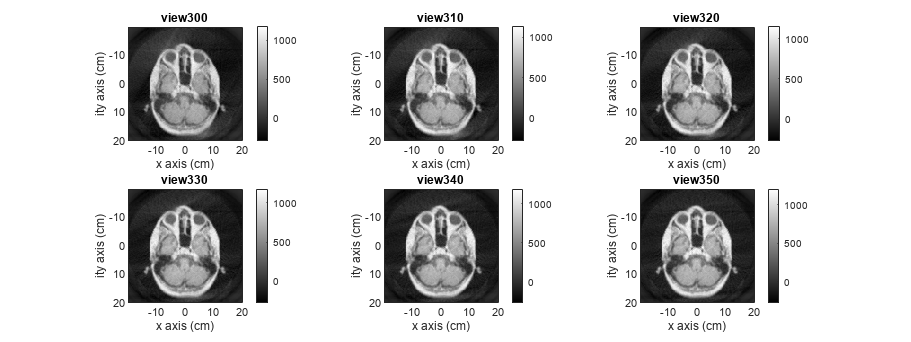

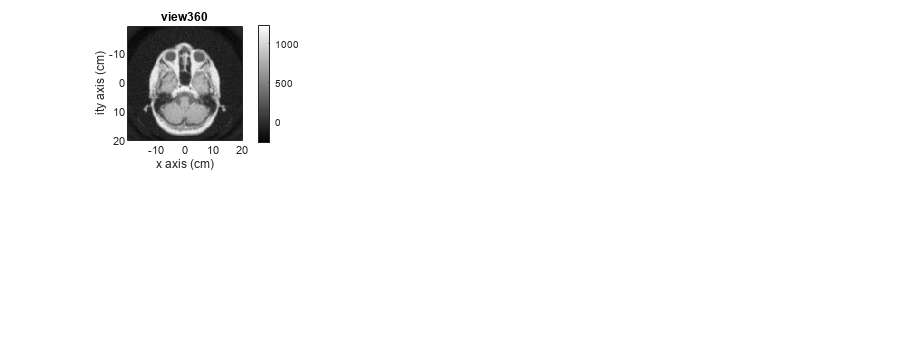

%疊加所有角度下的gxy影像得到最終的tomography圖像
tomography = zeros(height-1,width-1);
count = 6;
for deg = 0:360
    tomography = tomography + gxy3D(:,:,deg+1);
    %並每隔10度顯示一次
    a = rem(deg,10);
    if a == 0
        if count == 6
            count = count -5;
            fig = figure(); 
            fig.Position(3:4) = [8000, 3000];
        else
            count = count +1;
        end
        subplot(2,3,count)
        imagesc(t(2:end),t(2:end),tomography);colormap gray;colorbar;axis equal tight;
        xlabel('\itx axis (cm)');ylabel('ity axis (cm)')
        title(['view',num2str(deg)])
        drawnow
    end
end

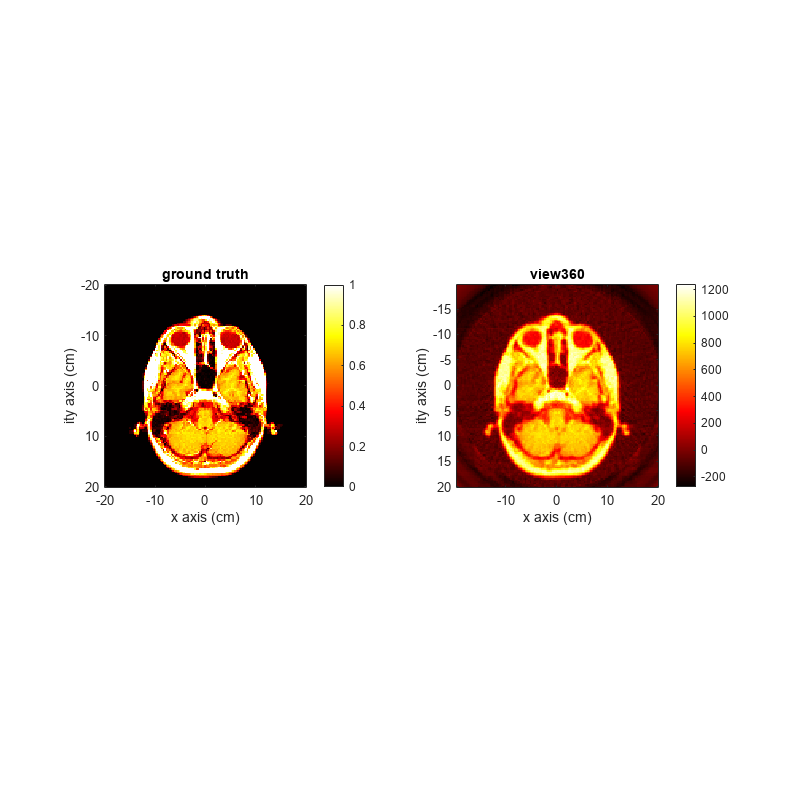

fig = figure;
fig.Position(3:4) = [1000, 1000];
subplot(1,2,1)
imagesc(t,s,sliceZ);colormap hot;colorbar;axis equal tight;
xlabel('\itx axis (cm)');ylabel('ity axis (cm)')
title('ground truth')
subplot(1,2,2)
imagesc(t(2:end),t(2:end),tomography);colormap hot;colorbar;axis equal tight;
xlabel('\itx axis (cm)');ylabel('ity axis (cm)')
title(['view',num2str(deg)])